# Decode CAN Data from BLF-Files

This example shows you how to import and decode CAN data from BLF-files in MATLAB for analysis. The BLF-file used in this example was generated from Vector CANoe™ using the "CAN - General System Configuration (CAN)" sample. This example also uses the CAN database file, `PowerTrain_BLF.dbc`, provided with the Vector sample configuration.

## Open the DBC-File

Open the database file describing the source CAN network using the [`canDatabase`](https://www.mathworks.com/help/vnt/ug/candatabase.html) function.

canDB = canDatabase("DEV1.dbc")

canDB =   Database with properties:

             Name: 'DEV1'
             Path: 'C:\Users\LJ Boone\Desktop\PLOT_DEV1_CAN\plotcanexample\DEV1.dbc'
        UTF8_File: 'C:\Users\LJ Boone\AppData\Local\Temp\tpe3269523_50be_43c7_9ad1_15765518b44d'
            Nodes: {4×1 cell}
         NodeInfo: [4×1 struct]
         Messages: {531×1 cell}
      MessageInfo: [531×1 struct]
       Attributes: {6×1 cell}
    AttributeInfo: [6×1 struct]
         UserData: []


## Investigate the BLF-File

Retrieve and view information about the BLF-File. The [`blfinfo`](https://www.mathworks.com/help/vnt/ug/blfinfo.html) function parses general information about the format and contents of the Vector Binary Logging Format BLF-file and returns the information as a structure.

binf = blfinfo("candata_test_9_1_22-1.blf")

binf = struct with fields:
                  Name: "candata_test_9_1_22-1.blf"
                  Path: "C:\Users\LJ Boone\Desktop\PLOT_DEV1_CAN\plotcanexample\candata_test_9_1_22-1.blf"
           Application: "CANalyzer"
    ApplicationVersion: "15.5.23"
               Objects: 433371
             StartTime: 01-Sep-2022 20:58:26.978
               EndTime: 01-Sep-2022 21:08:28.519
           ChannelList: [2×3 table]


binf.ChannelList

ans = 2×3 table
    ChannelID    Protocol    Objects
    _________    ________    _______

        1         "CAN"      430956 
        2         "CAN"           0 


## Read Data from BLF-File

The data of interest was logged from the powertrain bus which is stored in channel 2 of the BLF-file. Read the CAN data using the [`blfread`](https://www.mathworks.com/help/vnt/ug/blfread.html) function. You can also provide the DBC-file to the function call which will enable message name lookup and signal value decoding.

blfData = blfread("candata_test_9_1_22-1.blf", 1, "Database", canDB)

blfData = 430956×8 timetable
        Time         ID     Extended        Name                 Data             Length      Signals       Error    Remote
    _____________    ___    ________    ____________    ______________________    ______    ____________    _____    ______

    0.0010792 sec    513     false      {0×0 char  }    {[15 0 0 0 64 13 3 0]}      8       {0×0 struct}    false    false 
    0.0013574 sec    513     false      {0×0 char  }    {[15 0 0 0 64 13 3 0]}      8       {0×0 struct}    false    false 
    0.0014737 sec    128     false      {'SYNC'    }    {[                 0]}      1       {1×1 struct}    false    

View signals from an "EngineData" message.

blfData.Signals{3}

ans = struct with no fields.


## Repackage and Visualize Signal Values of Interest

Use the [`canSignalTimetable`](https://www.mathworks.com/help/vnt/ug/cansignaltimetable.html) function to repackage signal data from each unique message on the bus into a signal timetable. This example creates three individual signal timetables for the three messages of interest, "ABSdata", "EngineData" and "GearBoxInfo", from the CAN message timetable.

signalTimetable1 = canSignalTimetable(blfData, "N1_TPDO2")

signalTimetable1 = 77022×3 timetable
        Time         Phase_A_current    Electrical_angle    Current_Torque_Actual_Value
    _____________    _______________    ________________    ___________________________

    0.0020844 sec           3                  7                        971            
    0.0029793 sec           3                  6                        971            
    0.0038762 sec           3                  7                        971            
    0.0043267 sec           3                  7                        971            
    0.0047771 sec           3                  7                        971            
    0.0052316 sec           3                  6                        971            
    0.00568 

signalTimetable2 = canSignalTimetable(blfData, "N1_TPDO1")

signalTimetable2 = 77017×5 timetable
        Time         Current_demand    Logic_power_supply_voltage    DC_link_circuit_voltage    Motor_temperature    Controller_temperature
    _____________    ______________    __________________________    _______________________    _________________    ______________________

    0.0018821 sec          0                       0                           650                     18                      23          
    0.0025288 sec          0                       0                           650                     18                      23          
    0.0034258 sec          0                       0                           650                     18                      23          
    

% signalTimetable3 = canSignalTimetable(blfData, "GearBoxInfo")

To visualize the signals of interest, columns from the signal timetables can be plotted over time for further analysis.

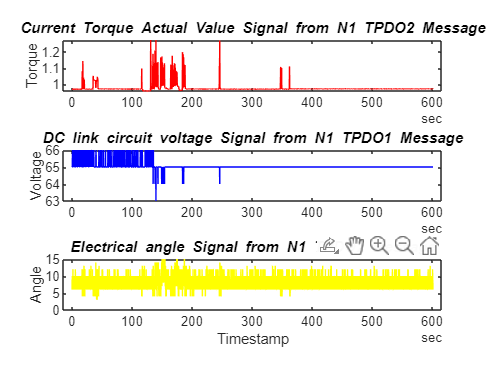

subplot(3, 1, 1)
plot(signalTimetable1.Time, signalTimetable1.Current_Torque_Actual_Value/1000, "r")
title("{\itCurrent Torque Actual Value} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Torque")
subplot(3, 1, 2)
plot(signalTimetable2.Time, signalTimetable2.DC_link_circuit_voltage/10, "b")
title("{\itDC link circuit voltage} Signal from {\itN1 TPDO1} Message", "FontWeight", "bold")
% xlabel("Timestamp")
ylabel("Voltage")
subplot(3, 1, 3)
plot(signalTimetable1.Time, signalTimetable1.Electrical_angle, "y")
title("{\itElectrical angle} Signal from {\itN1 TPDO2} Message", "FontWeight", "bold")
xlabel("Timestamp")
ylabel("Angle")

*Copyright 2020-2021 The MathWorks, Inc.*